data_path_

data_path = "d:/Sciebo/4G_5G_recordings"


handle = fopen(data_path + '/3627MHz_30720KSPS.sigmf-data', 'r'); % N_id_2 = 1, N_id_1 = 322
rxSampleRate = 30720000;
delta_f = -600e3;
f = 3672e6;
mu = 1;
apply_fine_CFO = 1;

% handle = fopen('30720KSPS_dl_signal.sigmf-data','r');
% rxSampleRate = 30720000;
% mu = 0


waveform_orig = fread(handle, 'int32');
fclose(handle);

waveform_orig = reshape(waveform_orig, 2, []);
waveform_orig = complex(waveform_orig(1, :), (-1)*waveform_orig(2, :))';
waveform_orig = waveform_orig / max(abs(waveform_orig));

waveform = waveform_orig .* exp(-1i*2*pi*delta_f/rxSampleRate * (0:length(waveform_orig)-1)');

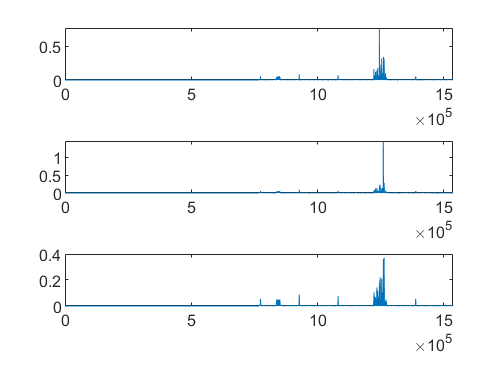


%% verify waveform with code from matlab examples
L_max = 8; % 4, 8 or 64
nrbSSB = 20;
scsSSB = 15 * 2^mu;
nSlot = 0;

peak_value = zeros(3,1);
peak_index = zeros(3,1);
carrierConfig = nrCarrierConfig('NSizeGrid', nrbSSB, 'SubcarrierSpacing', scsSSB);
waveform_search = waveform(1:rxSampleRate*25e-3);
for current_NID2 = [0 1 2]
    slotGrid = nrResourceGrid(carrierConfig, 1);
    pssIndices = (size(slotGrid,1)/2-63):1:(size(slotGrid,1)/2+63);
    slotGrid = slotGrid(:,1); % only 1 symbol
    slotGrid(pssIndices, 1) = nrPSS(current_NID2);
    [refWaveform, info] = nrOFDMModulate(carrierConfig, slotGrid, "SampleRate", rxSampleRate);
    refWaveform = refWaveform(info.CyclicPrefixLengths(1)+1:end); % remove CP

    corr = abs(xcorr(waveform_search, refWaveform));
    [peak_value(current_NID2+1), peak_index(current_NID2+1)] = max(corr);
    subplot(3,1,current_NID2+1);
    plot(corr);
end

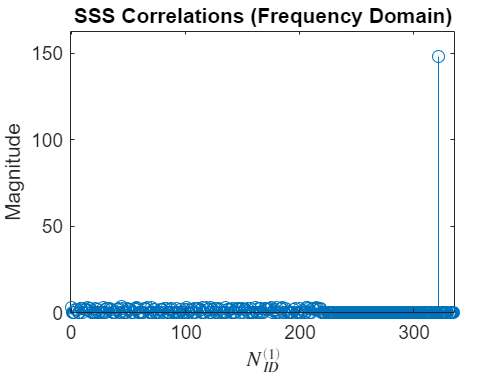

[x, detected_NID2] = max(peak_value);
detected_NID2 = detected_NID2-1;

%%
refGrid = zeros([nrbSSB*12 2]);
refGrid(nrPSSIndices,2) = nrPSS(detected_NID2);
% Timing estimation. This is the timing offset to the OFDM symbol prior to
% the detected SSB due to the content of the reference grid
if true
    timingOffset = nrTimingEstimate(waveform,nrbSSB,scsSSB,nSlot,refGrid,'SampleRate',rxSampleRate);
else
    % use same SSB as in python code
    % only for use with ideal file !
    mu = 0;
    cp1 = round(5.2e-6*Fs * 2^(-mu));
    cp2 = round(4.7e-6*Fs * 2^(-mu));
    timingOffset = 35264 - 2048 - cp1 - cp2;
end

% Synchronization, OFDM demodulation, and extraction of strongest SS block
rxGrid = nrOFDMDemodulate(waveform(1+timingOffset:end,:),nrbSSB,scsSSB,nSlot,'SampleRate',rxSampleRate);
rxGrid = rxGrid(:,2:5,:);

% Extract the received SSS symbols from the SS/PBCH block
sssIndices = nrSSSIndices;
sssRx = nrExtractResources(sssIndices,rxGrid);

% Correlate received SSS symbols with each possible SSS sequence
sssEst = zeros(1,336);
for NID1 = 0:335
    ncellid = (3*NID1) + detected_NID2;
    sssRef = nrSSS(ncellid);
    sssEst(NID1+1) = sum(abs(mean(sssRx .* conj(sssRef),1)).^2);
end
% Plot SSS correlations
figure;
stem(0:335,sssEst,'o');
title('SSS Correlations (Frequency Domain)');
xlabel('$N_{ID}^{(1)}$','Interpreter','latex');
ylabel('Magnitude');
axis([-1 336 0 max(sssEst)*1.1]);


% Determine NID1 by finding the strongest correlation
detected_NID1 = find(sssEst==max(sssEst)) - 1;

%%
detected_ncellid = (3*detected_NID1) + detected_NID2;

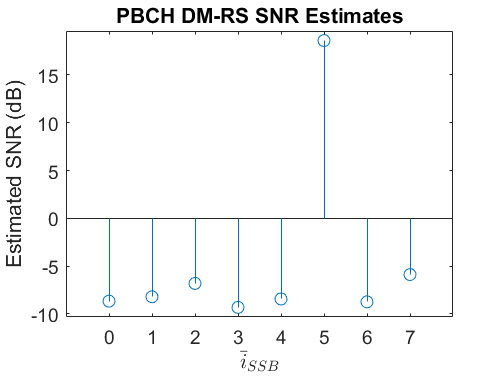




% Calculate PBCH DM-RS indices
dmrsIndices = nrPBCHDMRSIndices(detected_ncellid);

% Perform channel estimation using DM-RS symbols for each possible DM-RS
% sequence and estimate the SNR
dmrsEst = zeros(1,8);
for ibar_SSB = 0:7

    refGrid = zeros([240 4]);
    refGrid(dmrsIndices) = nrPBCHDMRS(detected_ncellid,ibar_SSB);
    [hest,nest] = nrChannelEstimate(rxGrid,refGrid,'AveragingWindow',[0 1]);
    dmrsEst(ibar_SSB+1) = 10*log10(mean(abs(hest(:).^2)) / nest);

end

% Plot PBCH DM-RS SNRs
figure;
stem(0:7,dmrsEst,'o');
title('PBCH DM-RS SNR Estimates');
xlabel('$\overline{i}_{SSB}$','Interpreter','latex');
xticks(0:7);
ylabel('Estimated SNR (dB)');
axis([-1 8 min(dmrsEst)-1 max(dmrsEst)+1]);

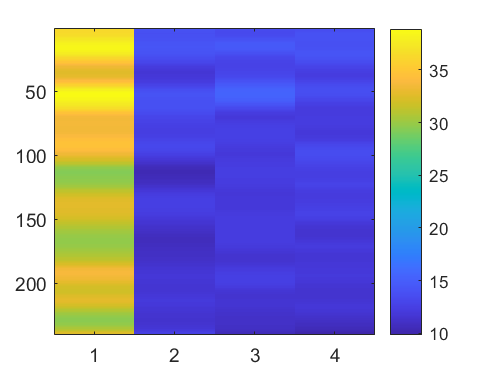


% Record ibar_SSB for the highest SNR
ibar_SSB = find(dmrsEst==max(dmrsEst)) - 1;

%%
refGrid = zeros([nrbSSB*12 4]);
refGrid(dmrsIndices) = nrPBCHDMRS(detected_ncellid,ibar_SSB);
refGrid(sssIndices) = nrSSS(detected_ncellid);
[hest,nest,hestInfo] = nrChannelEstimate(rxGrid,refGrid,'AveragingWindow',[0 1]);
image(abs(hest),'CDataMapping','scaled')
colorbar

%%
disp(' -- PBCH demodulation and BCH decoding -- ')

 -- PBCH demodulation and BCH decoding -- 


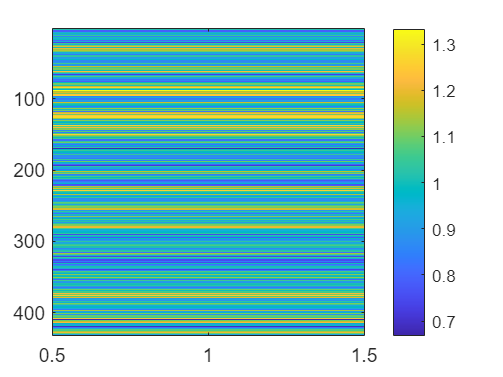


% Extract the received PBCH symbols from the SS/PBCH block
[pbchIndices,pbchIndicesInfo] = nrPBCHIndices(detected_ncellid);
pbchRx = nrExtractResources(pbchIndices,rxGrid);

% Configure 'v' for PBCH scrambling according to TS 38.211 Section 7.3.3.1
% 'v' is also the 2 LSBs of the SS/PBCH block index for L_max=4, or the 3
% LSBs for L_max=8 or 64.
if L_max == 4
    v = mod(ibar_SSB,4);
else
    v = ibar_SSB;
end
ssbIndex = v;

% PBCH equalization and CSI calculation
pbchHest = nrExtractResources(pbchIndices,hest);
[pbchEq,csi] = nrEqualizeMMSE(pbchRx,pbchHest,nest);
Qm = pbchIndicesInfo.G / pbchIndicesInfo.Gd;
csi = repmat(csi.',Qm,1);
csi = reshape(csi,[],1);
image(abs(pbchEq),'CDataMapping','scaled')
colorbar

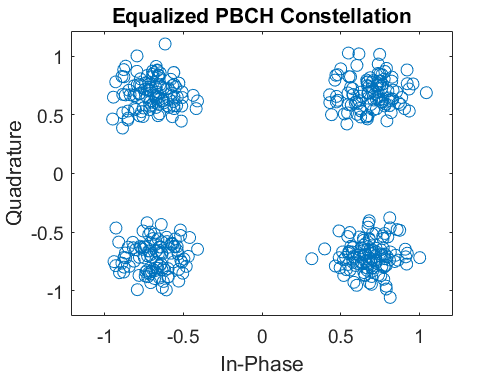



% Plot received PBCH constellation after equalization
figure;
plot(pbchEq,'o');
xlabel('In-Phase'); ylabel('Quadrature')
title('Equalized PBCH Constellation');
m = max(abs([real(pbchEq(:)); imag(pbchEq(:))])) * 1.1;
axis([-m m -m m]);


% PBCH demodulation, does also descrambling
pbchBits = nrPBCHDecode(pbchEq,detected_ncellid,v,nest);

% generate scrambling sequence just for debugging, TS38.11 7.3.3.1
E = 864; 
scrambling_seq = nrPBCHPRBS(detected_ncellid,v,E);

% Calculate RMS PBCH EVM
pbchRef = nrPBCH(pbchBits<0,detected_ncellid,v);
evm = comm.EVM;
pbchEVMrms = evm(pbchRef,pbchEq);

% Display calculated EVM
disp([' PBCH RMS EVM: ' num2str(pbchEVMrms,'%0.3f') '%']);

 PBCH RMS EVM: 17.718%



%%
% Apply CSI
pbchBits = pbchBits .* csi;

% Perform BCH decoding including rate recovery, polar decoding, and CRC
% decoding. PBCH descrambling and separation of the BCH transport block
% bits 'trblk' from 8 additional payload bits A...A+7 is also performed:
%   A ... A+3: 4 LSBs of system frame number
%         A+4: half frame number
% A+5 ... A+7: for L_max=64, 3 MSBs of the SS/PBCH block index
%              for L_max=4 or 8, A+5 is the MSB of subcarrier offset k_SSB
polarListLength = 8;
[scrblk,crcBCH,trblk,sfn4lsb,nHalfFrame,msbidxoffset] = ...
    nrBCHDecode(pbchBits,polarListLength,L_max,detected_ncellid);
%% 
% manual polar decoding and descrambling
if true
    iBIL = false;
    iIL = true;
    crcLen = 24;
    nMax = 9;
    A = 32;
    P = 24;
    K = A+P;
    N = get_3GPP_N(K,E,9);
    decIn = nrRateRecoverPolar(pbchBits,K,N,iBIL);
    decBits = nrPolarDecode(decIn,K,E,polarListLength,nMax,iIL,crcLen);
    %crc = decBits(end-23:end);
    [blk,err1] = nrCRCDecode(decBits,'24C');
    if err1
        disp(' BCH CRC is not zero.');
        return
    end
    if scrblk ~= blk(1:32)
        disp(' scrambled payload is not correct.');
        return
    end

    % descramble according to TS38.212 7.1.2
    if L_max == 4 || L_max == 8
        M = A-3;
    else
        M = A-6;
    end
    tmp_seq = nrPBCHPRBS(detected_ncellid,0,length(blk)*100);
    G = [16 23 18 17 8 30 10 6 24 7 0 5 3 2 1 4 9 11 12 13 14 15 19 20 21 22 25 26 27 28 29 31] + 1;
    PBCH_SFN_2ND_LSB_G = 10;
    PBCH_SFN_3RD_LSB_G = 9;
    v = 2*blk(PBCH_SFN_3RD_LSB_G) + blk(PBCH_SFN_2ND_LSB_G);
    n = v*M;
    scrambling_seq2 = tmp_seq(n+1:n+A);
    scrambling_seq3 = zeros(A,1);
    j = 1;
    for i = 1:A
        % SFN_2ND_LSB = 10, SFN_3RD_LSB = 9, half_frame_index= 11
        if i == G(11) || i == G(PBCH_SFN_2ND_LSB_G) || i == G(PBCH_SFN_3RD_LSB_G)  
            scrambling_seq3(i) = 0;
        else
            scrambling_seq3(i) = scrambling_seq2(j);
            j = j+1;
        end
    end
    tmp_seq2 = bitxor(blk, scrambling_seq3);
    if all(~tmp_seq2) || sum(tmp_seq2) < 10
        disp('manual descrambling works!')
    end

    tmp_seq3 = tmp_seq2(G);
    ber = comm.ErrorRate;
    errStats = ber(double(tmp_seq3(1:24)), double(trblk));
    disp([' Bit Error Rate: ' num2str(errStats(1))]);
end

 Bit Error Rate: 0.5



%%
% Display the BCH CRC
disp([' BCH CRC: ' num2str(crcBCH)]);

 BCH CRC: 0



% Stop processing MIB and SIB1 if BCH was received with errors
if crcBCH
    disp(' BCH CRC is not zero.');
    return
end

% Use 'msbidxoffset' value to set bits of 'k_SSB' or 'ssbIndex', depending
% on the number of SS/PBCH blocks in the burst
if (L_max==64)
    ssbIndex = ssbIndex + (bit2int(msbidxoffset,3) * 8);
    k_SSB = 0;
else
    k_SSB = msbidxoffset * 16;
end

% Displaying the SSB index
disp([' SSB index: ' num2str(ssbIndex)]);

 SSB index: 5
